## 3x+1 problem

### Background

Referring to this video: [https://www.youtube.com/watch?v=094y1Z2wpJg&ab_channel=Veritasium](https://www.youtube.com/watch?v=094y1Z2wpJg&ab_channel=Veritasium)

The 3x+1 problem states that if you take any (natural) number. If it is odd, multiply it by 3 and add 1. If it is even, divide it by two. 

For example, picking 7. Multiplying by 3 gives 21. Adding 1 gives 22. Now we have an even number, dividing it by 2 gives 11, which is uneven. Again, multiply by 3 and adding 1 gives 34, even. 

The problem is that, somehow, every number that can be chosen will end in a loop, going from 4 -> 2 -> 1 -> 4. So far, no number to start from is found that does not end in this loop, up to $2^{68}$. 

### Goal

The goal of this script is to get some insight in this mathematical problem and see if I can find a way to find a starting number that does not end in the 4-2-1 loop. 

### Initial idea

My initial idea was to start from the 4-2-1 loop and work my way back to any possible starting number. The 4-2-1 loop is always entered by arriving at a number that is $2^{n} \; \forall \; n = 1,\dots,\infty$. If arriving at these numbers can be avoided, the loop is avoided. 

### Example of the problem implemented in code 

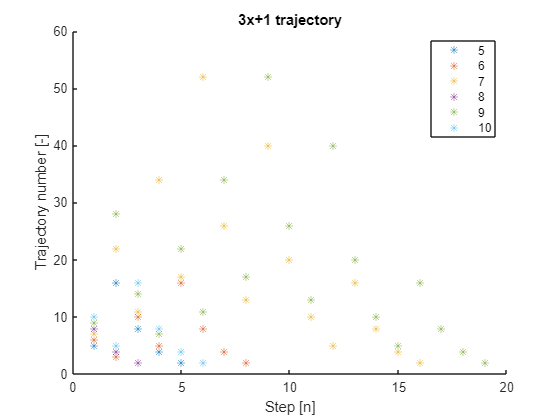

figure()
tryNumbers = 5:10;

for i = tryNumbers        % Test all start numbers in this given range 
    trajectory = 0;
    currentNumber = 0;
    
    % Run all trajectories untill 4-2-1 loop is reached
    while currentNumber ~= 1
        if currentNumber == 0
            currentNumber = i;      % Start at number i
        end

        trajectory = [trajectory, currentNumber];
        if (-1)^currentNumber == -1     % uneven            
            currentNumber = 3*currentNumber + 1;
        else    % even
            currentNumber = currentNumber / 2;
        end
    end
    
    % Reset
    currentNumber = 0;

    % Plot    
    hold on
    plot(1:length(trajectory)-1, trajectory(2:end),'*')
    hold off
    xlabel('Step [n]')
    ylabel('Trajectory number [-]')
    title('3x+1 trajectory')
end
legend(string(tryNumbers),'Location','Best')

Now, lets try what happens if we try to find all numbers that are leading to the 4-2-1 loop. Then, from these numbers, branch off by subtracting 1 and dividing by 3. TODO